close all

%For Population-scale COVID-19 Diagnostics Using a Compressed Barcode Space

%Define Params
eps = 0.0001;
b = 100000;
m = 10000;
m3 = 10;
m4 = 96;
m5 = 384;
k1 = 2;
k2 = 3;
k3 = 4; 
k4 = 5;
dstoch1 = 0.01;
dstoch2 = 0.05;
dsynth = 0.01;

%Initialize x-coordinates
x = logspace(-2,2);

n = x*b./100;

## Modeling with k_OPT

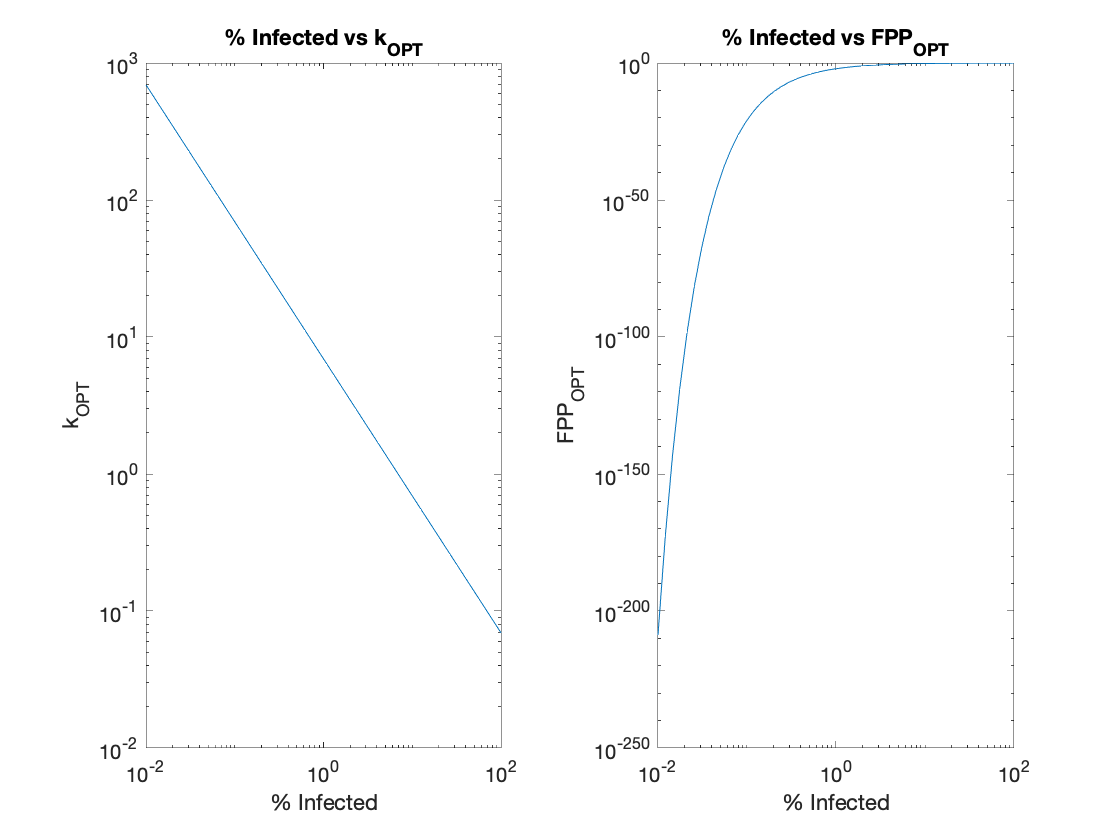

k_OPT = log(2)*m./n;
err = 0.5.^(log(2)*m./n);

figure(1)
tiledlayout(1, 2);

nexttile
loglog(x, k_OPT)
title("% Infected vs k_{OPT}")
ylabel("k_{OPT}")
xlabel("% Infected")

nexttile
loglog(x, err)
title("% Infected vs FPP_{OPT}")
ylabel("FPP_{OPT}")
xlabel("% Infected")

## Single Bloom Filter FPP, no Errors

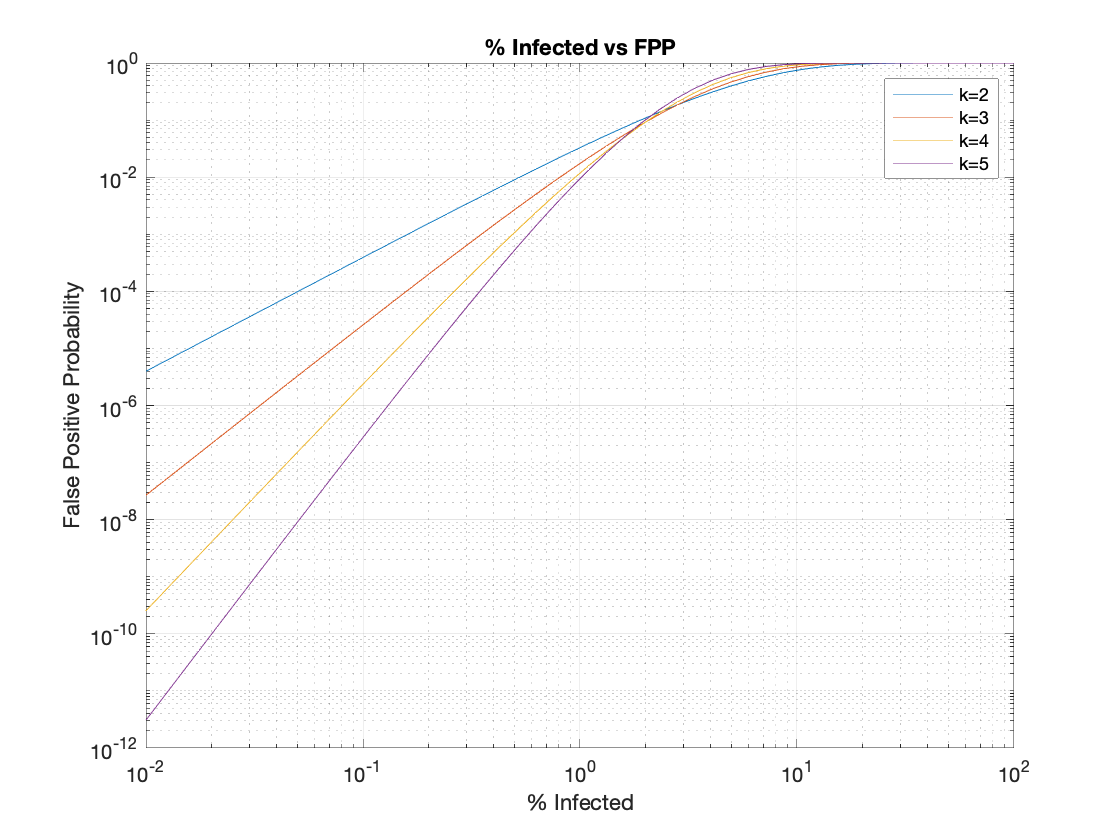

z1 = FPP(m, k1,  n);
z2 = FPP(m, k2,  n);
z3 = FPP(m, k3,  n);
z4 = FPP(m, k4,  n);

figure(2)
loglog(x,z1)
hold on
loglog(x,z2)
loglog(x,z3)
loglog(x,z4)
title("% Infected vs FPP")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("k=2", "k=3", "k=4", "k=5")
grid on

## Max Compression Factor, single Bloom Filter no Errors

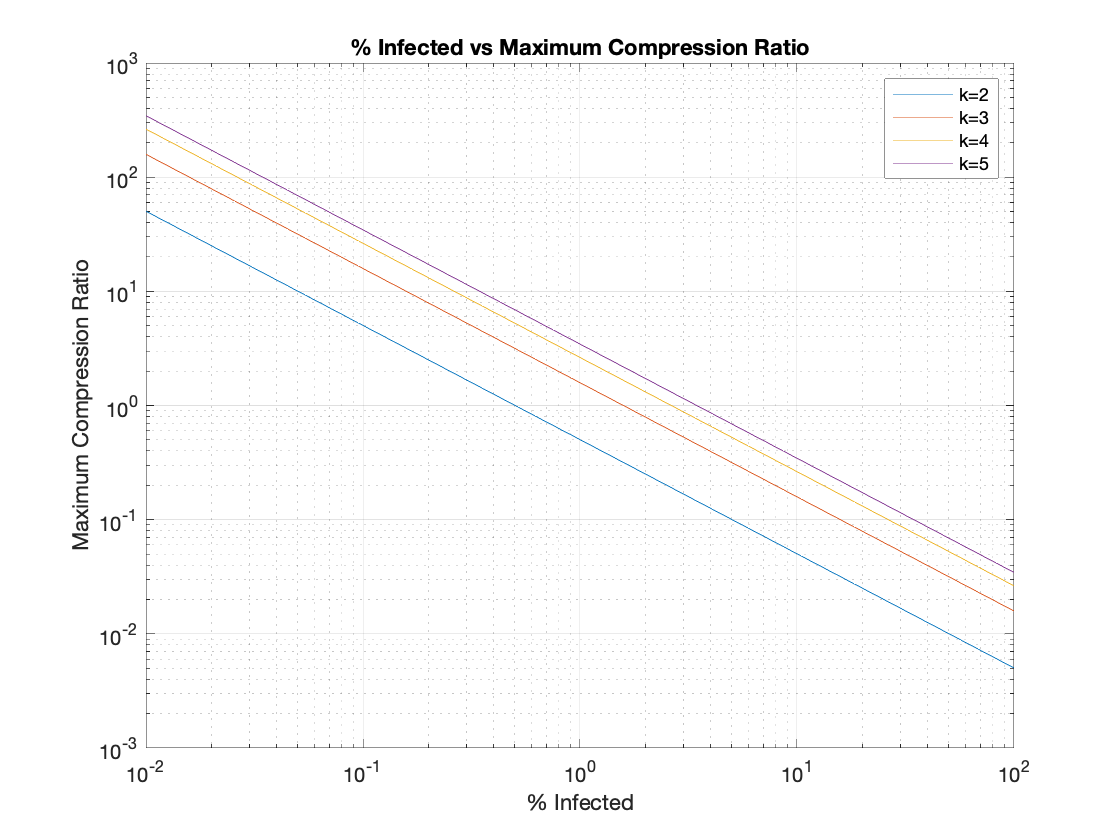

y1 = maxc(eps, k1, x);
y2 = maxc(eps, k2, x);
y3 = maxc(eps, k3, x);
y4 = maxc(eps, k4, x);

figure(3)
loglog(x,y1) 
hold on
loglog(x,y2)
loglog(x,y3)
loglog(x,y4)
title("% Infected vs Maximum Compression Ratio")
ylabel("Maximum Compression Ratio")
xlabel("% Infected")
legend("k=2", "k=3", "k=4", "k=5")
grid on

## FNP_{delta} for Bloom Filter with Errors

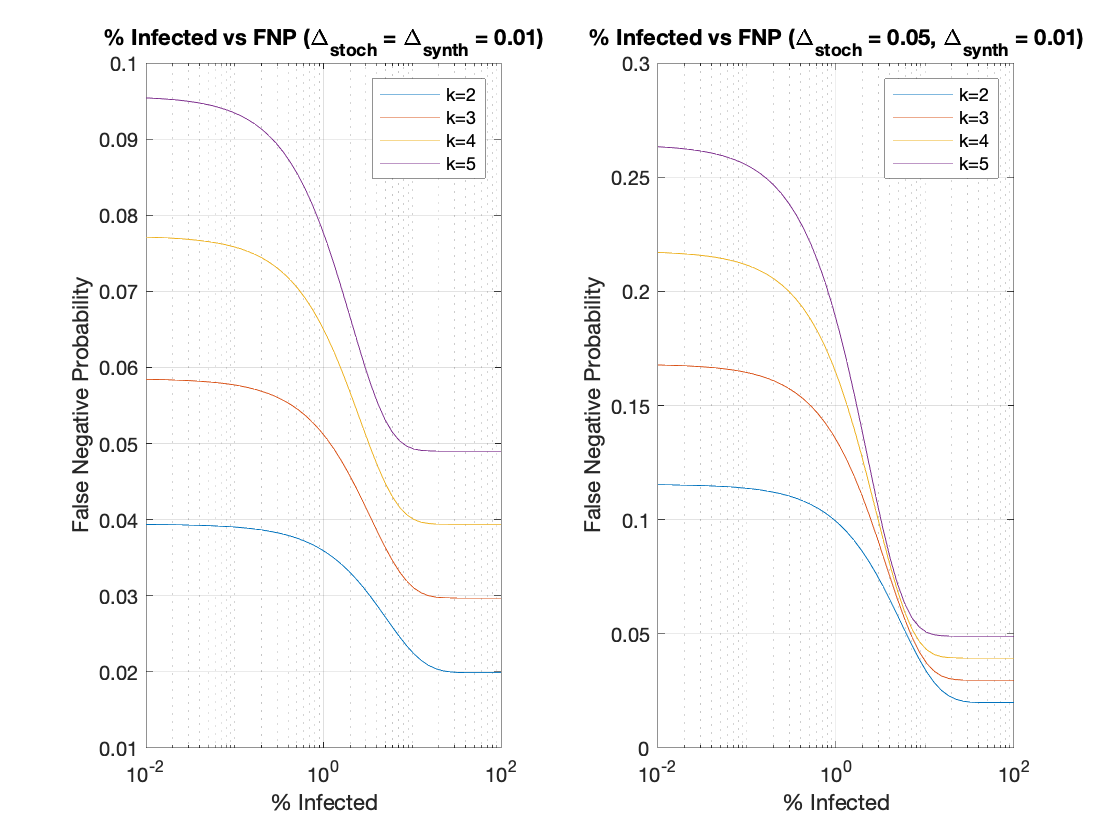

%r1 = 1-(1-dsynth).^k1*(1-dstoch1*exp(-k1*(1-dstoch1)*(x*b./100-1)./m)).^k1;
r1 = FNPdelta(m, k1, n, dstoch1, dsynth);
r2 = FNPdelta(m, k2, n, dstoch1, dsynth);
r3 = FNPdelta(m, k3, n, dstoch1, dsynth);
r4 = FNPdelta(m, k4, n, dstoch1, dsynth);

r5 = FNPdelta(m, k1, n, dstoch2, dsynth);
r6 = FNPdelta(m, k2, n, dstoch2, dsynth);
r7 = FNPdelta(m, k3, n, dstoch2, dsynth);
r8 = FNPdelta(m, k4, n, dstoch2, dsynth);

figure(4)
tiledlayout(1, 2);

nexttile
semilogx(x,r1) 
hold on
semilogx(x,r2)
semilogx(x,r3)
semilogx(x,r4)
title("% Infected vs FNP (\Delta_{stoch} = \Delta_{synth} = 0.01)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("k=2", "k=3", "k=4", "k=5")
grid on

nexttile
semilogx(x,r5) 
hold on
semilogx(x,r6)
semilogx(x,r7)
semilogx(x,r8)
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("k=2", "k=3", "k=4", "k=5")
grid on

## FNP_{delta} and FNP_{delta2} for Bloom Filter with Errors, k-1 out of k

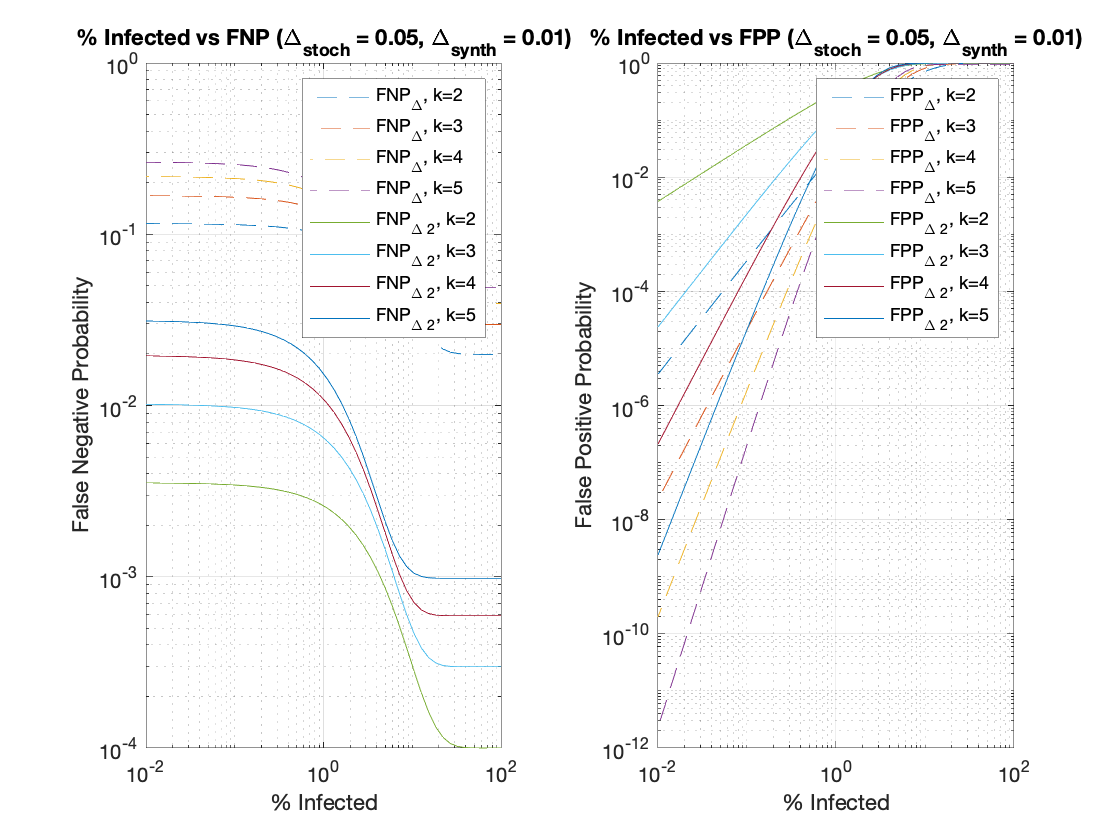

r5 = FNPdelta(m, k1, n, dstoch2, dsynth);
r6 = FNPdelta(m, k2, n, dstoch2, dsynth);
r7 = FNPdelta(m, k3, n, dstoch2, dsynth);
r8 = FNPdelta(m, k4, n, dstoch2, dsynth);

s1 = FNPdelta2(m, k1, n, dstoch2, dsynth);
s2 = FNPdelta2(m, k2, n, dstoch2, dsynth);
s3 = FNPdelta2(m, k3, n, dstoch2, dsynth);
s4 = FNPdelta2(m, k4, n, dstoch2, dsynth);

s5 = FPPdelta(m, k1, n, dstoch2, dsynth);
s6 = FPPdelta(m, k2, n, dstoch2, dsynth);
s7 = FPPdelta(m, k3, n, dstoch2, dsynth);
s8 = FPPdelta(m, k4, n, dstoch2, dsynth);

s9 = FPPdelta2(m, k1, n, dstoch2, dsynth);
s10 = FPPdelta2(m, k2, n, dstoch2, dsynth);
s11 = FPPdelta2(m, k3, n, dstoch2, dsynth);
s12 = FPPdelta2(m, k4, n, dstoch2, dsynth);

figure(5)
tiledlayout(1, 2);

nexttile
loglog(x,r5, '--')
hold on
loglog(x,r6, '--')
loglog(x,r7, '--')
loglog(x,r8, '--')
loglog(x,s1)
loglog(x,s2)
loglog(x,s3)
loglog(x,s4)
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("FNP_{\Delta}, k=2", "FNP_{\Delta}, k=3", "FNP_{\Delta}, k=4",...
    "FNP_{\Delta}, k=5", "FNP_{\Delta 2}, k=2", "FNP_{\Delta 2}, k=3",...
    "FNP_{\Delta 2}, k=4", "FNP_{\Delta 2}, k=5")
grid on

nexttile
loglog(x, s5, '--')
hold on
loglog(x, s6, '--')
loglog(x, s7, '--')
loglog(x, s8, '--')
loglog(x, s9)
loglog(x, s10)
loglog(x, s11)
loglog(x, s12)
title("% Infected vs FPP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01)")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("FPP_{\Delta}, k=2", "FPP_{\Delta}, k=3", "FPP_{\Delta}, k=4",...
    "FPP_{\Delta}, k=5", "FPP_{\Delta 2}, k=2", "FPP_{\Delta 2}, k=3",...
    "FPP_{\Delta 2}, k=4", "FPP_{\Delta 2}, k=5")
grid on

## FNP_{delta} and FNP_{delta2} for Bloom Filter with Errors, k-1 out of k,

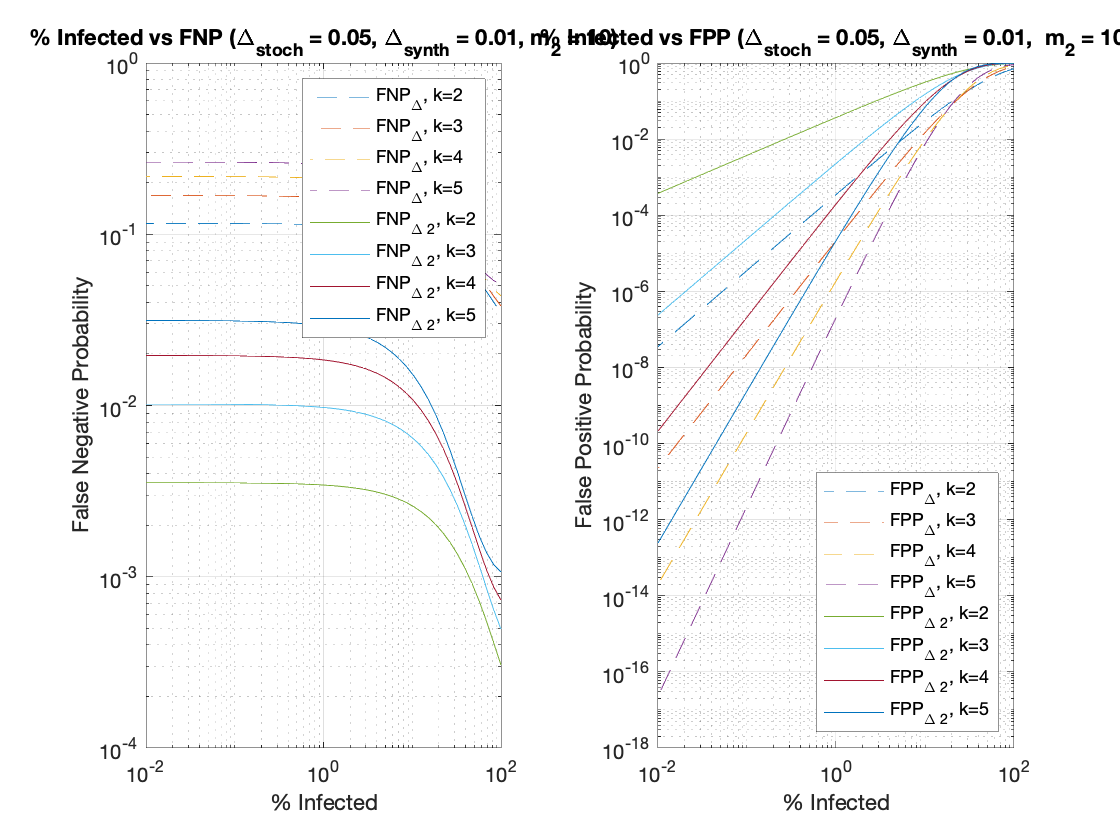

%with subbatches

t1 = FNPsubpool(m, k1, n, dstoch2, dsynth, m3);
t2 = FNPsubpool(m, k2, n, dstoch2, dsynth, m3);
t3 = FNPsubpool(m, k3, n, dstoch2, dsynth, m3);
t4 = FNPsubpool(m, k4, n, dstoch2, dsynth, m3);

t5 = FNPsubpool2(m, k1, n, dstoch2, dsynth, m3);
t6 = FNPsubpool2(m, k2, n, dstoch2, dsynth, m3);
t7 = FNPsubpool2(m, k3, n, dstoch2, dsynth, m3);
t8 = FNPsubpool2(m, k4, n, dstoch2, dsynth, m3);

t9 = FPPsubpool(m, k1, n, dstoch2, dsynth, m3);
t10 = FPPsubpool(m, k2, n, dstoch2, dsynth, m3);
t11 = FPPsubpool(m, k3, n, dstoch2, dsynth, m3);
t12 = FPPsubpool(m, k4, n, dstoch2, dsynth, m3);

t13 = FPPsubpool2(m, k1, n, dstoch2, dsynth, m3);
t14 = FPPsubpool2(m, k2, n, dstoch2, dsynth, m3);
t15 = FPPsubpool2(m, k3, n, dstoch2, dsynth, m3);
t16 = FPPsubpool2(m, k4, n, dstoch2, dsynth, m3);

u1 = FNPsubpool(m, k1, n, dstoch2, dsynth, m4);
u2 = FNPsubpool(m, k2, n, dstoch2, dsynth, m4);
u3 = FNPsubpool(m, k3, n, dstoch2, dsynth, m4);
u4 = FNPsubpool(m, k4, n, dstoch2, dsynth, m4);

u5 = FNPsubpool2(m, k1, n, dstoch2, dsynth, m4);
u6 = FNPsubpool2(m, k2, n, dstoch2, dsynth, m4);
u7 = FNPsubpool2(m, k3, n, dstoch2, dsynth, m4);
u8 = FNPsubpool2(m, k4, n, dstoch2, dsynth, m4);

u9 = FPPsubpool(m, k1, n, dstoch2, dsynth, m4);
u10 = FPPsubpool(m, k2, n, dstoch2, dsynth, m4);
u11 = FPPsubpool(m, k3, n, dstoch2, dsynth, m4);
u12 = FPPsubpool(m, k4, n, dstoch2, dsynth, m4);

u13 = FPPsubpool2(m, k1, n, dstoch2, dsynth, m4);
u14 = FPPsubpool2(m, k2, n, dstoch2, dsynth, m4);
u15 = FPPsubpool2(m, k3, n, dstoch2, dsynth, m4);
u16 = FPPsubpool2(m, k4, n, dstoch2, dsynth, m4);

v1 = FNPsubpool(m, k1, n, dstoch2, dsynth, m5);
v2 = FNPsubpool(m, k2, n, dstoch2, dsynth, m5);
v3 = FNPsubpool(m, k3, n, dstoch2, dsynth, m5);
v4 = FNPsubpool(m, k4, n, dstoch2, dsynth, m5);

v5 = FNPsubpool2(m, k1, n, dstoch2, dsynth, m5);
v6 = FNPsubpool2(m, k2, n, dstoch2, dsynth, m5);
v7 = FNPsubpool2(m, k3, n, dstoch2, dsynth, m5);
v8 = FNPsubpool2(m, k4, n, dstoch2, dsynth, m5);

v9 = FPPsubpool(m, k1, n, dstoch2, dsynth, m5);
v10 = FPPsubpool(m, k2, n, dstoch2, dsynth, m5);
v11 = FPPsubpool(m, k3, n, dstoch2, dsynth, m5);
v12 = FPPsubpool(m, k4, n, dstoch2, dsynth, m5);

v13 = FPPsubpool2(m, k1, n, dstoch2, dsynth, m5);
v14 = FPPsubpool2(m, k2, n, dstoch2, dsynth, m5);
v15 = FPPsubpool2(m, k3, n, dstoch2, dsynth, m5);
v16 = FPPsubpool2(m, k4, n, dstoch2, dsynth, m5);

figure(6)
tiledlayout(1, 2);

nexttile
loglog(x,t1, '--')
hold on
loglog(x,t2, '--')
loglog(x,t3, '--')
loglog(x,t4, '--')
loglog(x,t5)
loglog(x,t6)
loglog(x,t7)
loglog(x,t8)
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, m_2 = 10)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("FNP_{\Delta}, k=2", "FNP_{\Delta}, k=3", "FNP_{\Delta}, k=4",...
    "FNP_{\Delta}, k=5", "FNP_{\Delta 2}, k=2", "FNP_{\Delta 2}, k=3",...
    "FNP_{\Delta 2}, k=4", "FNP_{\Delta 2}, k=5")
grid on

nexttile
loglog(x, t9, '--')
hold on
loglog(x, t10, '--')
loglog(x, t11, '--')
loglog(x, t12, '--')
loglog(x, t13)
loglog(x, t14)
loglog(x, t15)
loglog(x, t16)
title("% Infected vs FPP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01,  m_2 = 10)")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("FPP_{\Delta}, k=2", "FPP_{\Delta}, k=3", "FPP_{\Delta}, k=4",...
    "FPP_{\Delta}, k=5", "FPP_{\Delta 2}, k=2", "FPP_{\Delta 2}, k=3",...
    "FPP_{\Delta 2}, k=4", "FPP_{\Delta 2}, k=5", 'Location', 'SouthEast')
grid on

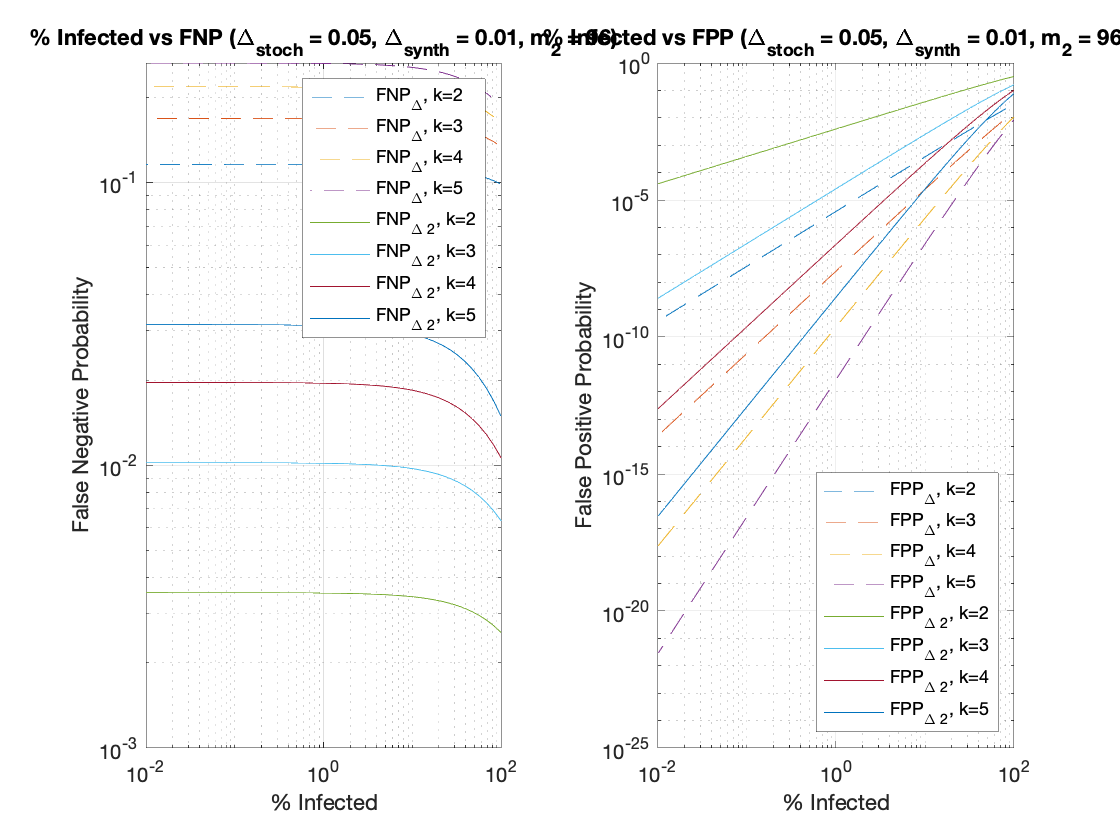

figure(7)
tiledlayout(1, 2);

nexttile
loglog(x,u1, '--')
hold on
loglog(x,u2, '--')
loglog(x,u3, '--')
loglog(x,u4, '--')
loglog(x,u5)
loglog(x,u6)
loglog(x,u7)
loglog(x,u8)
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, m_2 = 96)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("FNP_{\Delta}, k=2", "FNP_{\Delta}, k=3", "FNP_{\Delta}, k=4",...
    "FNP_{\Delta}, k=5", "FNP_{\Delta 2}, k=2", "FNP_{\Delta 2}, k=3",...
    "FNP_{\Delta 2}, k=4", "FNP_{\Delta 2}, k=5")
grid on

nexttile
loglog(x, u9, '--')
hold on
loglog(x, u10, '--')
loglog(x, u11, '--')
loglog(x, u12, '--')
loglog(x, u13)
loglog(x, u14)
loglog(x, u15)
loglog(x, u16)
title("% Infected vs FPP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, m_2 = 96)")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("FPP_{\Delta}, k=2", "FPP_{\Delta}, k=3", "FPP_{\Delta}, k=4",...
    "FPP_{\Delta}, k=5", "FPP_{\Delta 2}, k=2", "FPP_{\Delta 2}, k=3",...
    "FPP_{\Delta 2}, k=4", "FPP_{\Delta 2}, k=5", 'Location', 'SouthEast')
grid on

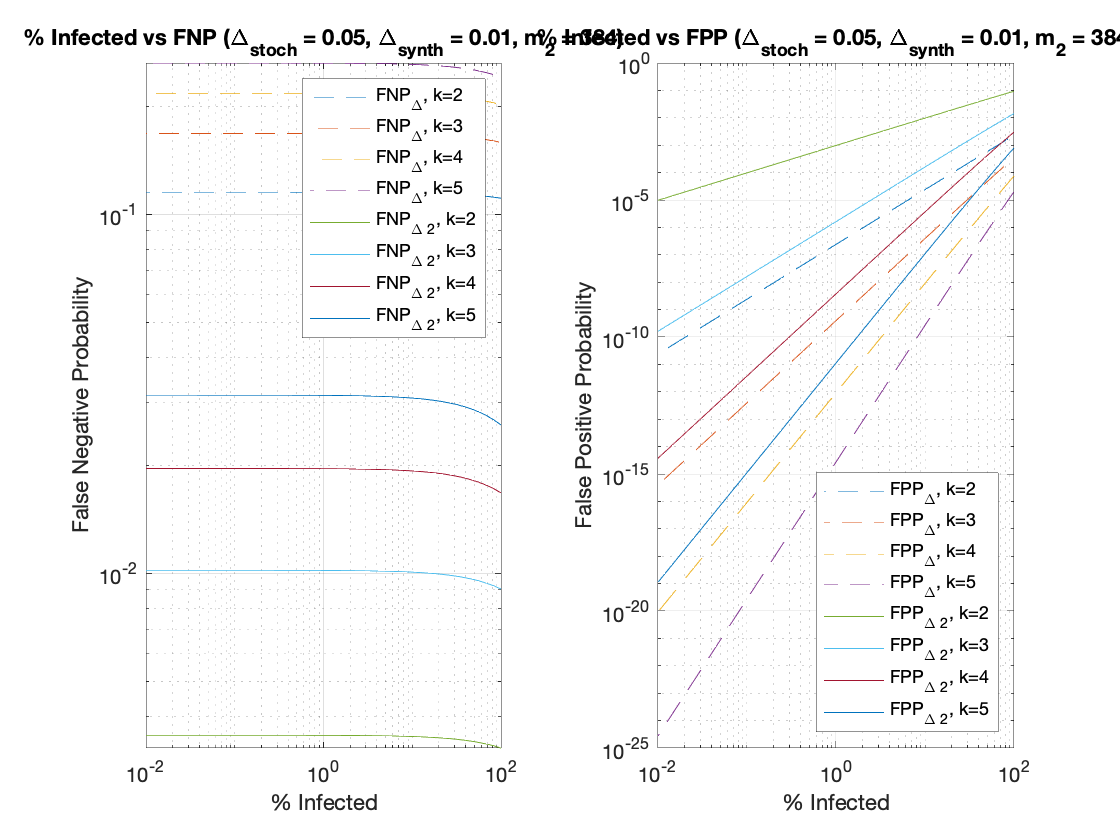


figure(8)
tiledlayout(1, 2);

nexttile
loglog(x,v1, '--')
hold on
loglog(x,v2, '--')
loglog(x,v3, '--')
loglog(x,v4, '--')
loglog(x,v5)
loglog(x,v6)
loglog(x,v7)
loglog(x,v8)
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, m_2 = 384)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("FNP_{\Delta}, k=2", "FNP_{\Delta}, k=3", "FNP_{\Delta}, k=4",...
    "FNP_{\Delta}, k=5", "FNP_{\Delta 2}, k=2", "FNP_{\Delta 2}, k=3",...
    "FNP_{\Delta 2}, k=4", "FNP_{\Delta 2}, k=5")
grid on

nexttile
loglog(x, v9, '--')
hold on
loglog(x, v10, '--')
loglog(x, v11, '--')
loglog(x, v12, '--')
loglog(x, v13)
loglog(x, v14)
loglog(x, v15)
loglog(x, v16)
title("% Infected vs FPP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, m_2 = 384)")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("FPP_{\Delta}, k=2", "FPP_{\Delta}, k=3", "FPP_{\Delta}, k=4",...
    "FPP_{\Delta}, k=5", "FPP_{\Delta 2}, k=2", "FPP_{\Delta 2}, k=3",...
    "FPP_{\Delta 2}, k=4", "FPP_{\Delta 2}, k=5", 'Location', 'SouthEast')
grid on

## DeltaK with subpools

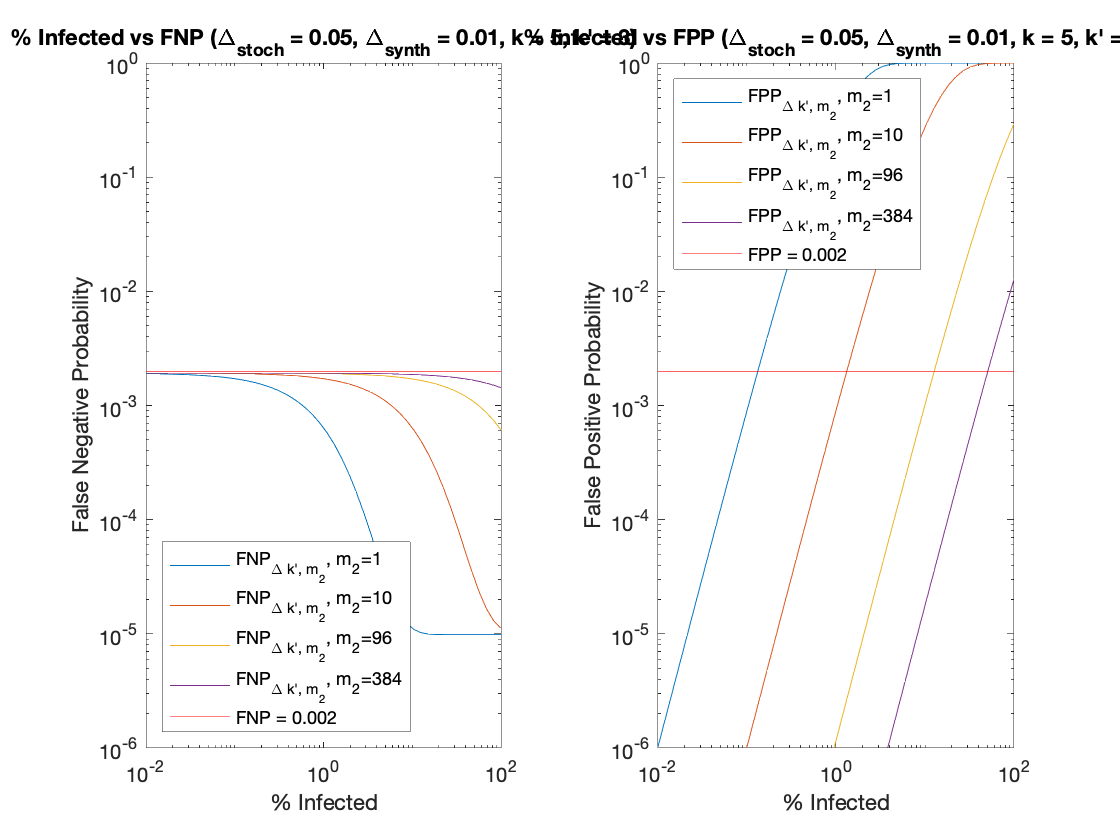

%{
w1 = FPPdeltak(m, 5, 3, n, 0, 0);
w2 = FPPsubpoolk(m, 5, 3, n, 0, 0, m3);
w3 = FPPsubpoolk(m, 5, 3, n, 0, 0, m4);
w4 = FPPsubpoolk(m, 5, 3, n, 0, 0, m5);
%}

w1 = FPPdeltak(m, 5, 3, n, dstoch2, dsynth);
w2 = FPPsubpoolk(m, 5, 3, n, dstoch2, dsynth, m3);
w3 = FPPsubpoolk(m, 5, 3, n, dstoch2, dsynth, m4);
w4 = FPPsubpoolk(m, 5, 3, n, dstoch2, dsynth, m5);

w5 = FNPdeltak(m, 5, 3, n, dstoch2, dsynth);
w6 = FNPsubpoolk(m, 5, 3, n, dstoch2, dsynth, m3);
w7 = FNPsubpoolk(m, 5, 3, n, dstoch2, dsynth, m4);
w8 = FNPsubpoolk(m, 5, 3, n, dstoch2, dsynth, m5);

figure(9)
tiledlayout(1, 2);

x2 = [0.01,100] ;
y2 = [0.002,0.002];
   
nexttile
loglog(x, w5)
hold on
loglog(x, w6)
loglog(x, w7)
loglog(x, w8)
plot(x2,y2,'-r')
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, k = 5, k' = 3)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("FNP_{\Delta k', m_2}, m_2=1", "FNP_{\Delta k', m_2}, m_2=10",...
    "FNP_{\Delta k', m_2}, m_2=96", "FNP_{\Delta k', m_2}, m_2=384",...
    "FNP = 0.002", 'Location', 'SouthWest')
ylim([10^(-6) 1])
grid off

nexttile
loglog(x, w1)
hold on
loglog(x, w2)
loglog(x, w3)
loglog(x, w4)
plot(x2,y2,'-r')
title("% Infected vs FPP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, k = 5, k' = 3)")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("FPP_{\Delta k', m_2}, m_2=1", "FPP_{\Delta k', m_2}, m_2=10",...
    "FPP_{\Delta k', m_2}, m_2=96", "FPP_{\Delta k', m_2}, m_2=384",...
    "FPP = 0.002", 'Location', 'NorthWest')
ylim([10^(-6) 1])
grid off

## Effect of varying m on FPP and FNP given p = 0.01, k=5, k' = 3

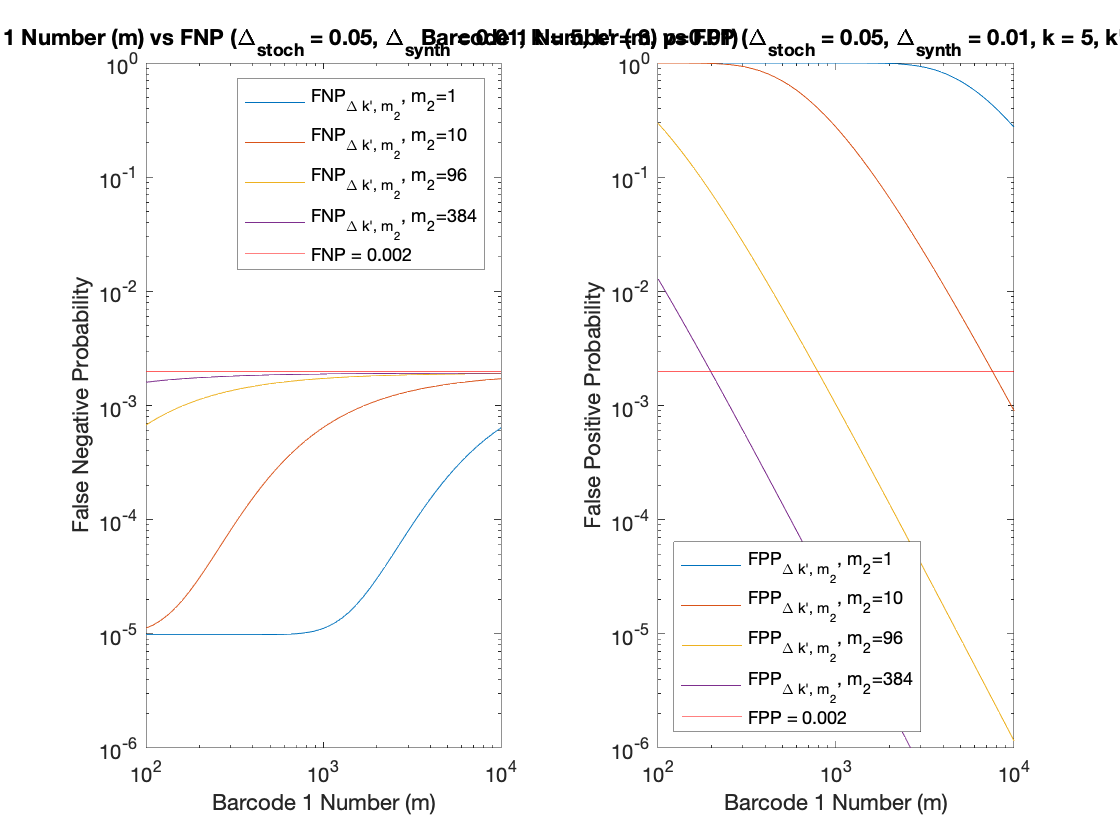

xm = logspace(2,4);
n2 = 0.01*b;
%{
l1 = FPPsubpoolk(xm, 5, 3, n2, 0, 0, 1);
l2 = FPPsubpoolk(xm, 5, 3, n2, 0, 0, m3);
l3 = FPPsubpoolk(xm, 5, 3, n2, 0, 0, m4);
l4 = FPPsubpoolk(xm, 5, 3, n2, 0, 0, m5);
%}

l1 = FPPsubpoolk(xm, 5, 3, n2, dstoch2, dsynth, 1);
l2 = FPPsubpoolk(xm, 5, 3, n2, dstoch2, dsynth, m3);
l3 = FPPsubpoolk(xm, 5, 3, n2, dstoch2, dsynth, m4);
l4 = FPPsubpoolk(xm, 5, 3, n2, dstoch2, dsynth, m5);

l5 = FNPsubpoolk(xm, 5, 3, n2, dstoch2, dsynth, 1);
l6 = FNPsubpoolk(xm, 5, 3, n2, dstoch2, dsynth, m3);
l7 = FNPsubpoolk(xm, 5, 3, n2, dstoch2, dsynth, m4);
l8 = FNPsubpoolk(xm, 5, 3, n2, dstoch2, dsynth, m5);

figure(10)
tiledlayout(1, 2);

x3 = [100,10000] ;
y3 = [0.002,0.002];

nexttile
loglog(xm, l5)
hold on
loglog(xm, l6)
loglog(xm, l7)
loglog(xm, l8)
plot(x3,y3,'-r')
title("Barcode 1 Number (m) vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, k = 5, k' = 3, p=0.01)")
ylabel("False Negative Probability")
xlabel("Barcode 1 Number (m)")
legend("FNP_{\Delta k', m_2}, m_2=1", "FNP_{\Delta k', m_2}, m_2=10",...
    "FNP_{\Delta k', m_2}, m_2=96", "FNP_{\Delta k', m_2}, m_2=384",...
    "FNP = 0.002",'Location', 'NorthEast')
ylim([10^(-6) 1])
grid off

nexttile
loglog(xm, l1)
hold on
loglog(xm, l2)
loglog(xm, l3)
loglog(xm, l4)
plot(x3,y3,'-r')
title("Barcode 1 Number (m) vs FPP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, k = 5, k' = 3, p=0.01)")
ylabel("False Positive Probability")
xlabel("Barcode 1 Number (m)")
legend("FPP_{\Delta k', m_2}, m_2=1", "FPP_{\Delta k', m_2}, m_2=10",...
    "FPP_{\Delta k', m_2}, m_2=96", "FPP_{\Delta k', m_2}, m_2=384",...
    "FPP = 0.002",'Location', 'SouthWest')
ylim([10^(-6) 1])
grid off

## Modified to m = 1000

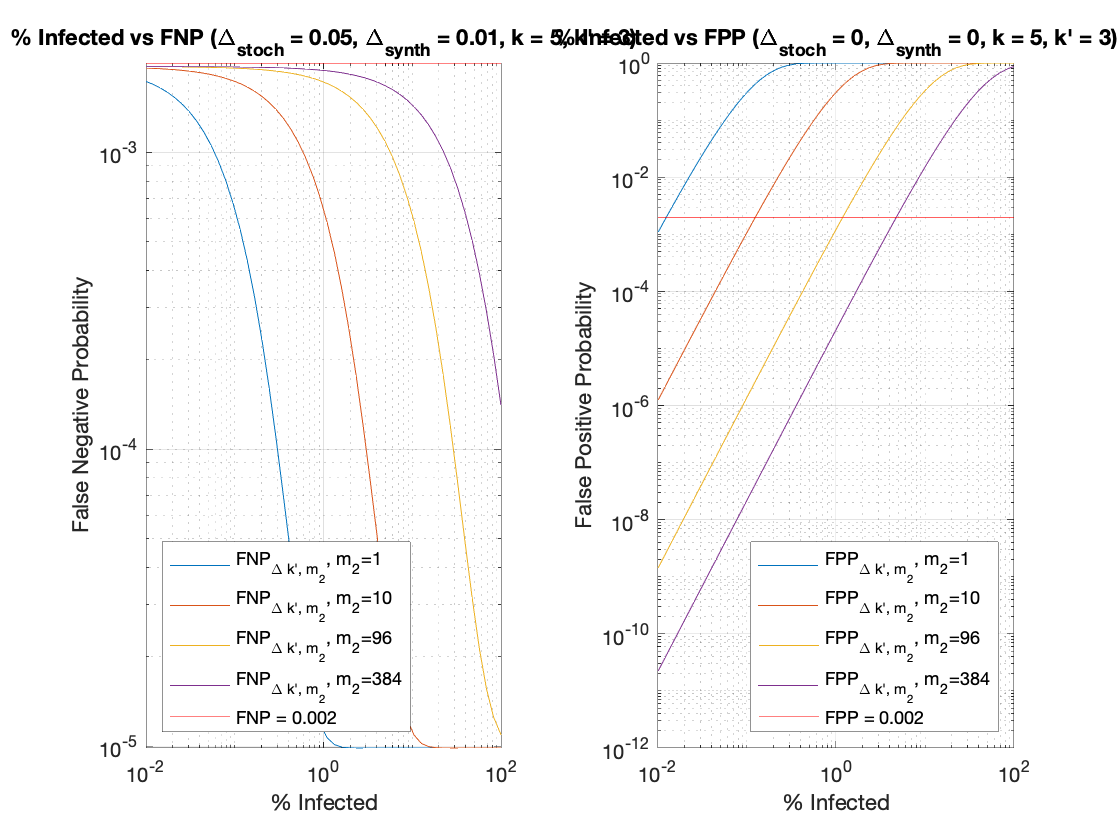

w21 = FPPdeltak(1000, 5, 3, n, 0, 0);
w22 = FPPsubpoolk(1000, 5, 3, n, 0, 0, m3);
w23 = FPPsubpoolk(1000, 5, 3, n, 0, 0, m4);
w24 = FPPsubpoolk(1000, 5, 3, n, 0, 0, m5);

w25 = FNPdeltak(1000, 5, 3, n, dstoch2, dsynth);
w26 = FNPsubpoolk(1000, 5, 3, n, dstoch2, dsynth, m3);
w27 = FNPsubpoolk(1000, 5, 3, n, dstoch2, dsynth, m4);
w28 = FNPsubpoolk(1000, 5, 3, n, dstoch2, dsynth, m5);

figure(11)
tiledlayout(1, 2);

x2 = [0.01,100] ;
y2 = [0.002,0.002];
   
nexttile
loglog(x, w25)
hold on
loglog(x, w26)
loglog(x, w27)
loglog(x, w28)
plot(x2,y2,'-r')
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, k = 5, k' = 3)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("FNP_{\Delta k', m_2}, m_2=1", "FNP_{\Delta k', m_2}, m_2=10",...
    "FNP_{\Delta k', m_2}, m_2=96", "FNP_{\Delta k', m_2}, m_2=384",...
    "FNP = 0.002", 'Location', 'SouthWest')
grid on

nexttile
loglog(x, w21)
hold on
loglog(x, w22)
loglog(x, w23)
loglog(x, w24)
plot(x2,y2,'-r')
title("% Infected vs FPP (\Delta_{stoch} = 0, \Delta_{synth} = 0, k = 5, k' = 3)")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("FPP_{\Delta k', m_2}, m_2=1", "FPP_{\Delta k', m_2}, m_2=10",...
    "FPP_{\Delta k', m_2}, m_2=96", "FPP_{\Delta k', m_2}, m_2=384",...
    "FPP = 0.002", 'Location', 'SouthEast')
grid on

## Modified to m = 384

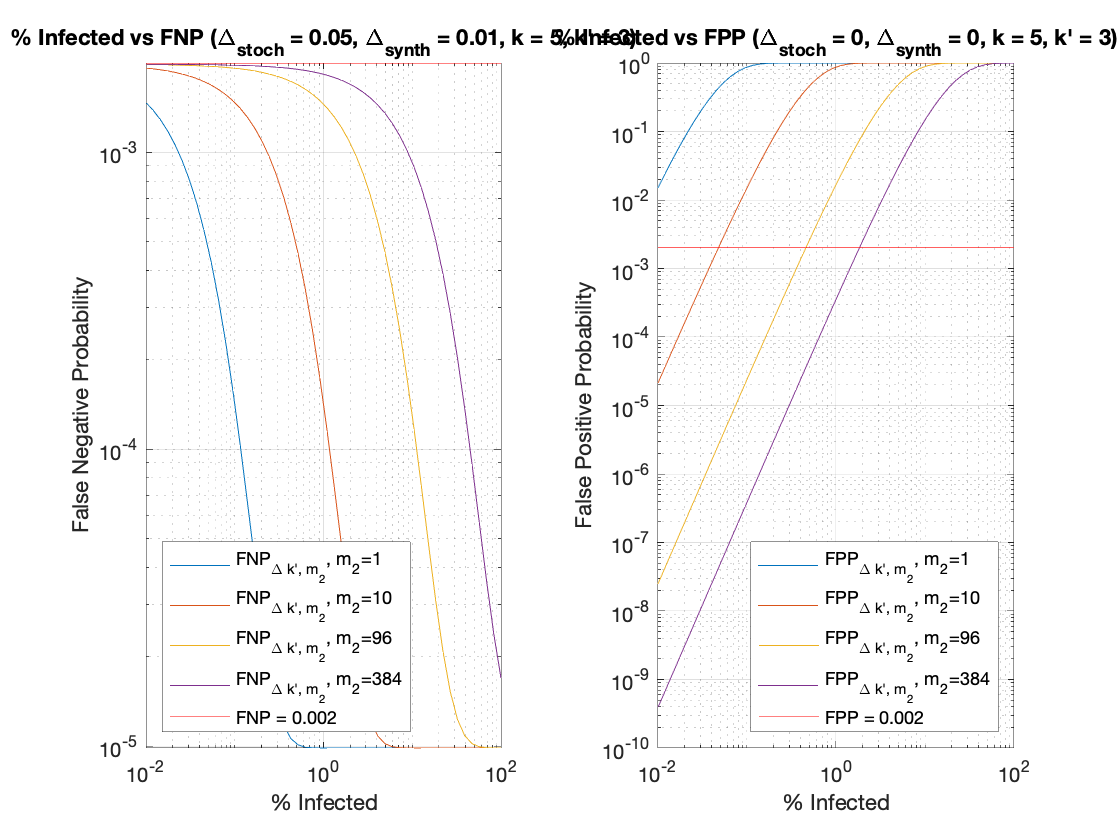

w31 = FPPdeltak(384, 5, 3, n, 0, 0);
w32 = FPPsubpoolk(384, 5, 3, n, 0, 0, m3);
w33 = FPPsubpoolk(384, 5, 3, n, 0, 0, m4);
w34 = FPPsubpoolk(384, 5, 3, n, 0, 0, m5);

w35 = FNPdeltak(384, 5, 3, n, dstoch2, dsynth);
w36 = FNPsubpoolk(384, 5, 3, n, dstoch2, dsynth, m3);
w37 = FNPsubpoolk(384, 5, 3, n, dstoch2, dsynth, m4);
w38 = FNPsubpoolk(384, 5, 3, n, dstoch2, dsynth, m5);

figure(12)
tiledlayout(1, 2);

x2 = [0.01,100] ;
y2 = [0.002,0.002];
   
nexttile
loglog(x, w35)
hold on
loglog(x, w36)
loglog(x, w37)
loglog(x, w38)
plot(x2,y2,'-r')
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, k = 5, k' = 3)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("FNP_{\Delta k', m_2}, m_2=1", "FNP_{\Delta k', m_2}, m_2=10",...
    "FNP_{\Delta k', m_2}, m_2=96", "FNP_{\Delta k', m_2}, m_2=384",...
    "FNP = 0.002", 'Location', 'SouthWest')
grid on

nexttile
loglog(x, w31)
hold on
loglog(x, w32)
loglog(x, w33)
loglog(x, w34)
plot(x2,y2,'-r')
title("% Infected vs FPP (\Delta_{stoch} = 0, \Delta_{synth} = 0, k = 5, k' = 3)")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("FPP_{\Delta k', m_2}, m_2=1", "FPP_{\Delta k', m_2}, m_2=10",...
    "FPP_{\Delta k', m_2}, m_2=96", "FPP_{\Delta k', m_2}, m_2=384",...
    "FPP = 0.002", 'Location', 'SouthEast')
grid on

## Figure 2C

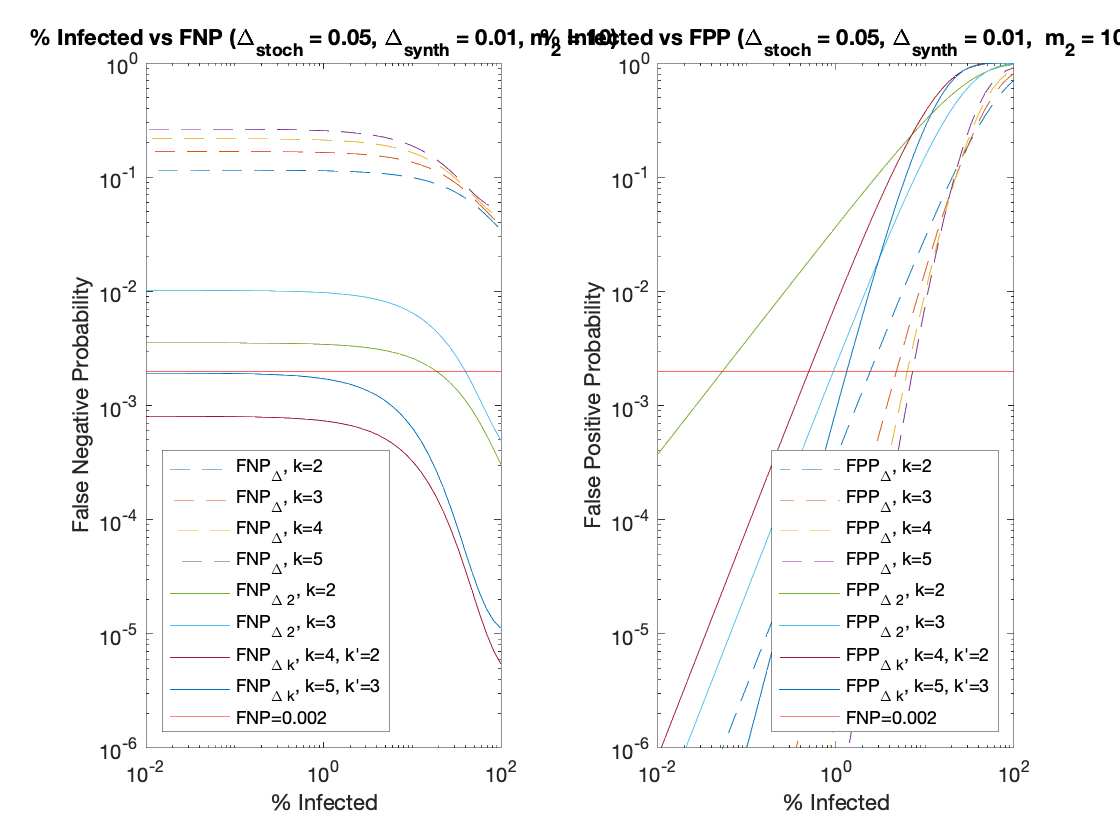

t21 = FNPsubpool(m, k1, n, dstoch2, dsynth, m3);
t22 = FNPsubpool(m, k2, n, dstoch2, dsynth, m3);
t23 = FNPsubpool(m, k3, n, dstoch2, dsynth, m3);
t24 = FNPsubpool(m, k4, n, dstoch2, dsynth, m3);

t25 = FNPsubpool2(m, k1, n, dstoch2, dsynth, m3);
t26 = FNPsubpool2(m, k2, n, dstoch2, dsynth, m3);
t27 = FNPsubpoolk(m, k3, 2, n, dstoch2, dsynth, m3);
t28 = FNPsubpoolk(m, k4, 3, n, dstoch2, dsynth, m3);

t29 = FPPsubpool(m, k1, n, dstoch2, dsynth, m3);
t30 = FPPsubpool(m, k2, n, dstoch2, dsynth, m3);
t31 = FPPsubpool(m, k3, n, dstoch2, dsynth, m3);
t32 = FPPsubpool(m, k4, n, dstoch2, dsynth, m3);

t33 = FPPsubpool2(m, k1, n, dstoch2, dsynth, m3);
t34 = FPPsubpool2(m, k2, n, dstoch2, dsynth, m3);
t35 = FPPsubpoolk(m, k3, 2, n, dstoch2, dsynth, m3);
t36 = FPPsubpoolk(m, k4, 3, n, dstoch2, dsynth, m3);

figure(13)
tiledlayout(1, 2);

nexttile
loglog(x,t21, '--')
hold on
loglog(x,t22, '--')
loglog(x,t23, '--')
loglog(x,t24, '--')
loglog(x,t25)
loglog(x,t26)
loglog(x,t27)
loglog(x,t28)
plot(x2,y2,'-r')
title("% Infected vs FNP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01, m_2 = 10)")
ylabel("False Negative Probability")
xlabel("% Infected")
legend("FNP_{\Delta}, k=2", "FNP_{\Delta}, k=3", "FNP_{\Delta}, k=4",...
    "FNP_{\Delta}, k=5", "FNP_{\Delta 2}, k=2", "FNP_{\Delta 2}, k=3",...
    "FNP_{\Delta k}, k=4, k'=2", "FNP_{\Delta k}, k=5, k'=3",...
    "FNP=0.002",'Location', 'SouthWest')
ylim([10^(-6) 1])
grid off

nexttile
loglog(x, t29, '--')
hold on
loglog(x, t30, '--')
loglog(x, t31, '--')
loglog(x, t32, '--')
loglog(x, t33)
loglog(x, t34)
loglog(x, t35)
loglog(x, t36)
plot(x2,y2,'-r')
title("% Infected vs FPP (\Delta_{stoch} = 0.05, \Delta_{synth} = 0.01,  m_2 = 10)")
ylabel("False Positive Probability")
xlabel("% Infected")
legend("FPP_{\Delta}, k=2", "FPP_{\Delta}, k=3", "FPP_{\Delta}, k=4",...
    "FPP_{\Delta}, k=5", "FPP_{\Delta 2}, k=2", "FPP_{\Delta 2}, k=3",...
    "FPP_{\Delta k}, k=4, k'=2", "FPP_{\Delta k}, k=5, k'=3",...
    "FNP=0.002",'Location', 'SouthEast')
ylim([10^(-6) 1])
grid off

%% Functions
%Idealized Bloom filter, no errors

function a = FPP(m, k, n)
    a = (1-(1-1/m).^(k*n)).^k;
end

function b = maxc(eps, k, x)
    b =-log(1-eps^(1/k))./(k*x)*100;
end

%Functions for FNP and FPP incorporating errors, original Bloom filter
%model (k out of k)
function c = FPPdelta(m, k, n, dstoch, dsynth)
    c = ((1-dsynth)*(1-(1-(1-dstoch)./m).^(k*n))).^k;
end

function d = FNPdelta(m, k, n, dstoch, dsynth)
    d = 1-(1-dsynth).^k*(1-dstoch*exp(-k*(1-dstoch)*(n-1)./m)).^k;
end

function e = FNPdeltamax(k, dstoch, dsynth)
    e = 1-(1-dsynth).^k*(1-dstoch).^k;
end

%Functions for FNP and FPP with k-  1 out of k model
function f = FPPdelta2(m, k, n, dstoch, dsynth)
    f = FPPdelta(m, k, n, dstoch, dsynth)...
        +k.*((1-dsynth).*(1-(1-(1-dstoch)/m).^(k*n))).^(k-1)...
        .*(dsynth+(1-dsynth)*(1-(1-dstoch)/m).^(k*n));
end

function g = FNPdelta2(m, k, n, dstoch, dsynth)
    g = FNPdelta(m, k, n, dstoch, dsynth)...
    -k.*((1-dsynth).*(1-dstoch.*(1-(1-dstoch)/m).^(k*(n-1)))).^(k-1)...
    .*(dsynth+(1-dsynth).*dstoch.*(1-(1-dstoch)/m).^(k*(n-1)));
end

function h = FNPdelta2max(k, dstoch, dsynth)
    h = 1-(1-dsynth).^k*(1-dstoch).^k...
        -k.*((1-dsynth).*(1-dstoch)).^(k-1).*(dsynth+(1-dsynth).*dstoch);
end

%Functions for FNP and FPP with k' out of k model
function f = FPPdeltak(m, k, ktwo, n, dstoch, dsynth)
    ftwo = 0;
    for s =ktwo:k
        ftwo = ftwo+nchoosek(k, s).*((1-dsynth).*(1-(1-(1-dstoch)./m).^(k*n))).^(s)...
        .*(dsynth+(1-dsynth)*(1-(1-dstoch)./m).^(k*n)).^(k-s);
    end
    f = ftwo;
end


function g = FNPdeltak(m, k, ktwo, n, dstoch, dsynth)
    gtwo = 1;
    for s=ktwo:k
        gtwo = gtwo-nchoosek(k,s)*((1-dsynth).*(1-dstoch.*(1-(1-dstoch)./m)...
            .^(k*(n-1)))).^(s).*(dsynth+(1-dsynth).*dstoch.*...
            (1-(1-dstoch)./m).^(k*(n-1))).^(k-s);
    end
    g = gtwo;
end

%Functions for FNP and FPP with subpools
function k = FNPsubpool(m, k, n, dstoch, dsynth, m2)
    k = FNPdelta(m, k, n/m2, dstoch, dsynth);
end

function l = FPPsubpool(m, k, n, dstoch, dsynth, m2)
    l = FPPdelta(m, k, n/m2, dstoch, dsynth);
end

function m = FNPsubpool2(m, k, n, dstoch, dsynth, m2)
    m = FNPdelta2(m, k, n/m2, dstoch, dsynth);
end

function n = FPPsubpool2(m, k, n, dstoch, dsynth, m2)
    n = FPPdelta2(m, k, n/m2, dstoch, dsynth);
end

function m = FNPsubpoolk(m, k, ktwo, n, dstoch, dsynth, m2)
    m = FNPdeltak(m, k, ktwo, n/m2, dstoch, dsynth);
end

function n = FPPsubpoolk(m, k, ktwo, n, dstoch, dsynth, m2)
    n = FPPdeltak(m, k, ktwo, n/m2, dstoch, dsynth);
end

